
clear;close all
Tum_ID = csvread('B16F10_IDg.csv',2,0); %B16F10 Experimental Data
global k
global counter
counter = 1;


% Initializing arrays for time, tumour draining and control lymph nodes,
% blood, and tumour values. 
HPI = Tum_ID(:,1);
TILN_Mean =  Tum_ID(:,2);
TILN_SD =  Tum_ID(:,3);
ILN_Mean = Tum_ID(:,4);
ILN_SD = Tum_ID(:,5);
Bld_Mean = Tum_ID(:,6);
Bld_SD = Tum_ID(:,7);
Tumor_Mean = Tum_ID(:,8); 
Tumor_SD = Tum_ID(:,9);

% Rate constants and initial conditions in compartment model solved using
% nested optimization using fminseachbnd, which constrains the optimized
% vairables to positive values. 
% fminsearchbnd can be downloaded in the MathWorks file exchange in the
% link: https://www.mathworks.com/matlabcentral/fileexchange/8277-fminsearchbnd-fminsearchcon
options = optimset('MaxIter',100);
[IC_Tumor,fval] = fminsearchbnd(@(IC) IC_opt(HPI,[Bld_Mean TILN_Mean ILN_Mean Tumor_Mean],...
    [Bld_SD*0.01 TILN_SD*0.0001 ILN_SD*0.0001 Tumor_SD*0.00001],IC),...
    [30 1 1 1],[10 0 0 0],[90 3 3 3],options);  

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 285317.224626 

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 203300.808636 

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 477800.566224 

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 298047.190916 

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 200868.984401 

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 214749.671598 

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 558316.662422 


Plotting Model Predictions Again Experimental Data

% Print k and initial condition values. 
IC_Tumor'

ans =    32.2255
    0.8709
    1.1738
    1.0941


k'

ans = 	1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0069
    4.6101


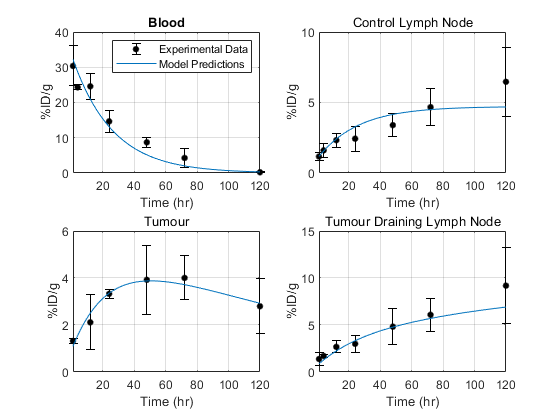


% Solves system of equations with exit tracking variable with optimized k and initial condition values 
[x,y] = ode45(@(t,y) system3(t,y,k),[HPI(1):0.5:HPI(end)],[IC_Tumor(1:3) 0 IC_Tumor(4) 0 0 0 0 0 0]);

% Result plotting
figure()
subplot(2,2,1)
hold on
set(0,'DefaultAxesTitleFontWeight','normal');
errorbar(HPI,Bld_Mean,Bld_SD,'.k','MarkerSize',15)
plot(x,y(:,1),'Color',[0, 0.4470, 0.7410]);box on;grid on;title('Blood')
ylabel('%ID/g');xlabel('Time (hr)');xlim([1 120])
legend('Experimental Data','Model Predictions')
hold off

subplot(2,2,4)
hold on
errorbar(HPI,TILN_Mean,TILN_SD,'.k','MarkerSize',15)
plot(x,y(:,2)+y(:,6),'Color',[0, 0.4470, 0.7410]); 
box on;grid on;title('Tumour Draining Lymph Node')
ylabel('%ID/g');xlabel('Time (hr)');xlim([1 120])
hold off

subplot(2,2,2)
hold on
errorbar(HPI,ILN_Mean,ILN_SD,'.k','MarkerSize',15)
plot(x,y(:,3)+y(:,7),'Color',[0, 0.4470, 0.7410])
box on;grid on;title('Control Lymph Node');xlim([1 120])
ylabel('%ID/g');xlabel('Time (hr)')
hold off

subplot(2,2,3)
hold on
errorbar(HPI(Tumor_Mean ~= 0),Tumor_Mean(Tumor_Mean ~= 0),Tumor_SD(Tumor_Mean ~= 0),'.k','MarkerSize',15)
plot(x,y(:,4)+y(:,5),'Color',[0, 0.4470, 0.7410]);box on;grid on;
ylabel('%ID/g');xlabel('Time (hr)');xlim([1 120])
title('Tumour')
hold off

Calculation of Lymphatic and Blood Exit Quantities

figure()
Lymph_Drainage = y(end,11) %Lymphatic Exit Amount after 120hr

Lymph_Drainage = 2.5263

Intravasation = y(end,10) % Blood Exit Amount after 120hr

Intravasation = 0.0144

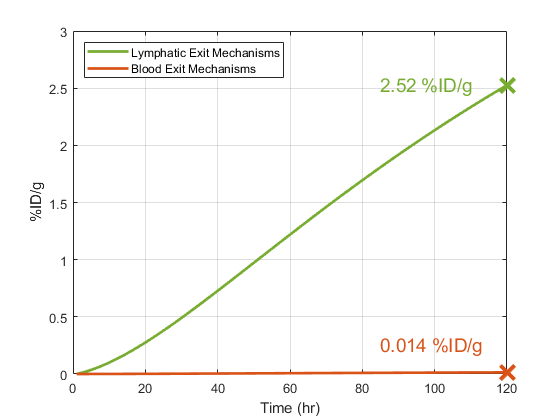


% Plotting Lymphatic and Blood Exit Over Time
hold on
plot(x,y(:,11),'Color',[0.4660, 0.6740, 0.1880],'LineWidth',2)
plot(x,y(:,10),'Color',[0.8500, 0.3250, 0.0980],'LineWidth',2)
plot(x(end), y(end,11),'x','MarkerSize',15,'Color',[0.4660, 0.6740, 0.1880],'LineWidth',3) 
plot(x(end), y(end,10),'x','MarkerSize',15,'Color',[0.8500, 0.3250, 0.0980],'LineWidth',3) 
legend('Lymphatic Exit Mechanisms','Blood Exit Mechanisms','Location','northwest')
ylabel('%ID/g')
xlabel('Time (hr)')
box on;grid on;

text(85,y(end,11),[num2str(2.52),' %ID/g'],'FontSize',14,'Color',[0.4660, 0.6740, 0.1880])
text(85,0.25,[num2str(0.014),' %ID/g'],'FontSize',14,'Color',[0.8500, 0.3250, 0.0980])

hold off


% Ratio of Lymphatic Exit to Blood Exit
Ratio = (Intravasation/Lymph_Drainage)^-1

Ratio = 175.2599

Goodness of Fit Assessment using R^2

REAL_Y = [Bld_Mean;TILN_Mean;ILN_Mean;Tumor_Mean(Tumor_Mean~=0)];
Index = x == HPI';
Index = logical(sum(Index')');

Index_Tumor = x == HPI(Tumor_Mean~=0)';
Index_Tumor = logical(sum(Index_Tumor')');


FIT_Y = [y(Index,1);y(Index,2)+y(Index,6);y(Index,3)+y(Index,7);y(Index_Tumor,4)+y(Index_Tumor,5)];
[R, P, RLO, RUP] = corrcoef([REAL_Y FIT_Y ])

R =     1.0000    0.9816
    0.9816    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RLO =     1.0000    0.9596
    0.9596    1.0000


RUP =     1.0000    0.9917
    0.9917    1.0000


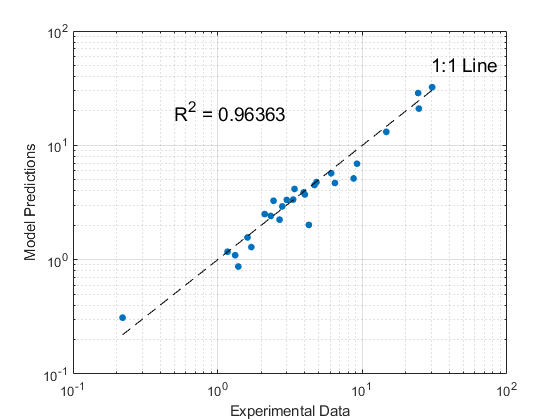


figure()
hold on
scatter(REAL_Y,FIT_Y,300,'.')
plot([min(REAL_Y):max(REAL_Y)],[min(REAL_Y):max(REAL_Y)],'--k')
text(0.5,20,['R^2 = ',num2str(R(2)^2)],'FontSize',14)
text(30,50,['1:1 Line'],'FontSize',14)
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
ylabel('Model Predictions')
xlabel('Experimental Data')
box on

grid on


R2_Blood = corrcoef([Bld_Mean y(Index,1) ]).^2

R2_Blood =     1.0000    0.9561
    0.9561    1.0000


R2_TILN = corrcoef([TILN_Mean y(Index,2)+y(Index,6) ]).^2

R2_TILN =     1.0000    0.9339
    0.9339    1.0000


R2_ILN  = corrcoef([ILN_Mean y(Index,3)+y(Index,7) ]).^2

R2_ILN =     1.0000    0.8029
    0.8029    1.0000


R2_Tumor = corrcoef([Tumor_Mean(Tumor_Mean~=0) y(Index_Tumor,4)+y(Index_Tumor,5)]).^2

R2_Tumor =     1.0000    0.9448
    0.9448    1.0000


SSE Calculations

Bld_SSE_Timescaled = sum(((HPI/100).*(Bld_Mean-y(Index,1))./Bld_Mean).^2)

Bld_SSE_Timescaled = 0.4298

TILN_SSE_Timescaled = sum(((HPI/100).*(TILN_Mean-y(Index,2)-y(Index,6))./TILN_Mean).^2)

TILN_SSE_Timescaled = 0.0921

ILN_SSE_Timescaled = sum(((HPI/100).*(ILN_Mean-y(Index,3)-y(Index,7))./ILN_Mean).^2)

ILN_SSE_Timescaled = 0.1286

Tumor_SSE_Timescaled = sum(((HPI(Tumor_Mean~=0)/100).*(Tumor_Mean(Tumor_Mean~=0)-y(Index_Tumor,4)-y(Index_Tumor,5))./Tumor_Mean(Tumor_Mean~=0)).^2)

Tumor_SSE_Timescaled = 0.0062

SSE_Timescaled_Tumor = Tumor_SSE_Timescaled

SSE_Timescaled_Tumor = 0.0062

SSE_Timescaled_LN = TILN_SSE_Timescaled+ILN_SSE_Timescaled

SSE_Timescaled_LN = 0.2207

Sensitivity Analysis

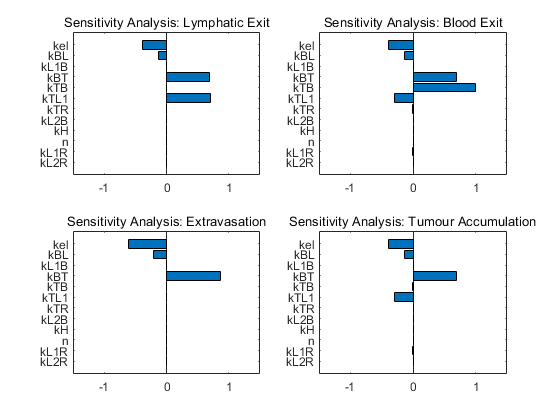

% Calls the function sensitivity_analysis to perturb model k values by 10%
% and calculate the magnitude of change on model predictors. 
[dLymph,dIntra,dExtra,dTumorAUC] = sensitivity_analysis(@system3,HPI,[IC_Tumor(1:3) 0 IC_Tumor(4) 0 0 0 0 0 0],k);
bar_labels=["kel",'kBL','kL1B','kBT','kTB','kTL1','kTR','kL2B','kH','n','kL1R','kL2R'];
figure()
subplot(2,2,1)
set(0,'DefaultAxesTitleFontWeight','normal');
barh(flip(dLymph))
xlim([-1.5 1.5])
yticklabels(flip(bar_labels))
title('Sensitivity Analysis: Lymphatic Exit','FontSize',10)
subplot(2,2,2)
barh(flip(dIntra))
xlim([-1.5 1.5])
yticklabels(flip(bar_labels))
title('Sensitivity Analysis: Blood Exit','FontSize',10)
subplot(2,2,3)
barh(flip(dExtra))
xlim([-1.5 1.5])
yticklabels(flip(bar_labels))
title('Sensitivity Analysis: Extravasation','FontSize',10)
subplot(2,2,4)
barh(flip(dTumorAUC))
xlim([-1.5 1.5])
yticklabels(flip(bar_labels))
title('Sensitivity Analysis: Tumour Accumulation','FontSize',10)

Testing Model Predictions on Unseen Data

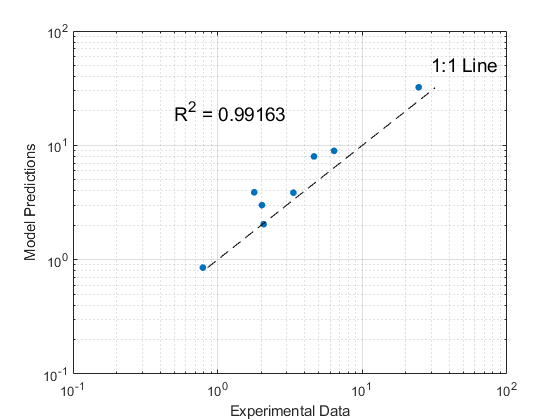

% Testing model predictions against data withheld form model development. 
Index_8hr = find(x==8);
Index_96hr = find(x==96);
y_predicted = [y(Index_8hr,1);y(Index_96hr,1);
    y(Index_8hr,2)+y(Index_8hr,6);y(Index_96hr,2)+y(Index_96hr,6);
    y(Index_8hr,3)+y(Index_8hr,7);y(Index_96hr,3)+y(Index_96hr,7);
    y(Index_8hr,4)+y(Index_8hr,5);y(Index_96hr,4)+y(Index_96hr,5);];

% %IDg of experimental data gathered at 8hr and 96hr post-nanoparticle
% injection. Experimental data was gathered following model development. 
y_measured = [32.19401686
               0.852679188
               3.885005681
               8.950966166
               2.998527698
                8.00039985
               2.042929328
               3.852756847];

R_test = corrcoef([y_predicted y_measured ]);

figure()
hold on
scatter(y_predicted,y_measured,300,'.')
plot([min(y_measured):max(y_measured)],[min(y_measured):max(y_measured)],'--k')
text(0.5,20,['R^2 = ',num2str(R_test(2)^2)],'FontSize',14)
text(30,50,['1:1 Line'],'FontSize',14)
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
ylabel('Model Predictions')
xlabel('Experimental Data')
xlim([10^-1 10^2])
ylim([10^-1 10^2])
box on;grid on

Optimizer Functions

%The function IC_opt optimizes for the initial conditions (at 1hr) giventhe current values of k

function [E] = IC_opt(t,y,std,IC) 
global k

    k = [0.025 10^-5 10 0.001 0.001 0.01 0.01 10^-7 1 100 1 0.01]; % Initial guesses  
    y_true = y;
    y(1,:) = IC;
    

    options2 = optimset('MaxIter',1050);
    k = fminsearchbnd(@(P) k_opt(t,y,y_true,std,P),k,...
        [0.025 0 0 0 0 0 0 0 0 0 0 0],...
        [Inf Inf Inf Inf Inf Inf Inf Inf Inf Inf Inf Inf],options2);
    
    % Solves for model predictions given current best guess for k and
    % initial condition values
    [x,y_fit] = ode23(@(t,y) system(t,y,k),[t(1):1:t(end)],[y(1,1) y(1,2) y(1,3) 0 y(1,4) 0 0]);
    in = x == t';
    y_guess = zeros(size(y));
    
    % Extracts the current model predictions at experimental timepoints
    for i = 1:size(in,2)
       y_guess(i,1) = y_fit(in(:,i)',1);
       y_guess(i,2) = y_fit(in(:,i)',2);
       y_guess(i,3) = y_fit(in(:,i)',3);
       y_guess(i,4) = y_fit(in(:,i)',4);
       y_guess(i,5) = y_fit(in(:,i)',5);
       y_guess(i,6) = y_fit(in(:,i)',6);
       y_guess(i,7) = y_fit(in(:,i)',7);
    end

    y_guess(:,2) =  y_guess(:,2)+ y_guess(:,6);
    y_guess(:,3) =  y_guess(:,3)+ y_guess(:,7);
    y_guess(:,5) =  y_guess(:,5)+ y_guess(:,4);
    
    
    % Error calculation between model predictions and experimental timepoints    
    E1 = sum(sum(((y_true(:,1:3)-y_guess(:,1:3)).^2)./std(:,1:3)));  
    E2 = sum(sum(((y_guess((y_true(:,4) ~=0),5) - y_true((y_true(:,4) ~=0),4)).^2)./std((y_true(:,4) ~=0),4)));
    E = E1+E2;
end


function [E] = k_opt(t,y,y_true,std,P)     
    y_store = []; 
    y_store(1,:) = y(1,:); 
    
    y_store(1,5) = y_store(1,4);
    y_store(1,4) = 0;
    y_store(1,6) = 0;
    y_store(1,7) = 0;

    % Solves for model predictions given current best guess for k and
    % initial condition values
    i=1;
    while i<= length(t)-1
        [n,m] = ode23(@(t,y) system(t,y,P'),[t(i),t(i+1)],y_store(i,:));
        y_store(i+1,:) = m(end,:);
        i=i+1;
    end
    
    % Extracts the current model predictions at experimental timepoints
    y_store(:,2) =  y_store(:,2)+ y_store(:,6);
    y_store(:,3) =  y_store(:,3)+ y_store(:,7);
    y_store(:,5) =  y_store(:,5)+ y_store(:,4);
    
    % Error calculation between model predictions and experimental timepoints  
    E1 = sum(sum(((y_true(:,1:3)-y_store(:,1:3)).^2)./std(:,1:3))); 
    E2 = sum(sum(((y_store((y_true(:,4) ~=0),5) - y_true((y_true(:,4) ~=0),4)).^2)./std((y_true(:,4) ~=0),4)));
    E = E1+E2;
end



System of Equations Functions

% The function system() contains the system of ODEs descibing the nanoparticle amounts
% in the four compartments. The k values are the rate constants and the descriptions are included below.
% The function system3() includes variables to track nanoparticle exit out of the tumour and into the lymphatics and blood  

% k(1): Blood -> Out
% k(2): Blood -> LN (Equal for each LN)
% k(3): T-ILN -> Blood
% k(4): Blood -> ECM
% k(5): ECM -> Blood (Intravasation)
% k(6): ECM -> T-ILN (Lymph Drainage)
% k(7): ECM -> Cell
% k(8): ILN -> Blood
% k(9): K
% k(10) n
% k(11): T-ILN sink
% k(12)L ILN sink
    
function Dy = system(t,y,k) 
    dy1 = k(5)*y(5)+k(3)*y(2)+k(8)*y(3) - (k(1)+2*k(2)+k(4))*y(1); %Blood Compartment
    dy2 = k(6)*y(5)+k(2)*y(1)-k(3)*y(2)-k(11)*y(2); %Tumour Lymph Node Compartment
    dy3 = k(2)*y(1)-k(8)*y(3) - k(12)*y(3); %Control Lymph Node Compartment
    dy4 = k(7)*y(5)*(1+(y(4)/k(9))^k(10))^-1 ; %Tumour Sink
    dy5 = k(4)*y(1) - (k(5)+k(6)+k(7)*(1+(y(4)/k(9))^k(10))^-1)*y(5); %Tumour 
    dy6 = k(11)*y(2); %T-ILN Sink
    dy7 = k(12)*y(3); %ILN Sink
    Dy = [dy1;dy2;dy3;dy4;dy5;dy6;dy7];
end

function Dy = system3(t,y,k) 
    dy1 = k(5)*y(5)+k(3)*y(2)+k(8)*y(3) - (k(1)+2*k(2)+k(4))*y(1); 
    dy2 = k(6)*y(5)+k(2)*y(1)-k(3)*y(2)-k(11)*y(2); 
    dy3 = k(2)*y(1)-k(8)*y(3) - k(12)*y(3); 
    dy4 = k(7)*y(5)*(1+(y(4)/k(9))^k(10))^-1 ; 
    dy5 = k(4)*y(1) - (k(5)+k(6)+k(7)*(1+(y(4)/k(9))^k(10))^-1)*y(5); 
    dy6 = k(11)*y(2); 
    dy7 = k(12)*y(3);
    dy8 = k(1)*y(1);
    dy9 = k(4)*y(1); % Extravasation
    dy10 = k(5)*y(5); % Intravastaion 
    dy11 = k(6)*y(5); % Lymph Drainage
    Dy = [dy1;dy2;dy3;dy4;dy5;dy6;dy7;dy8;dy9;dy10;dy11];
end
